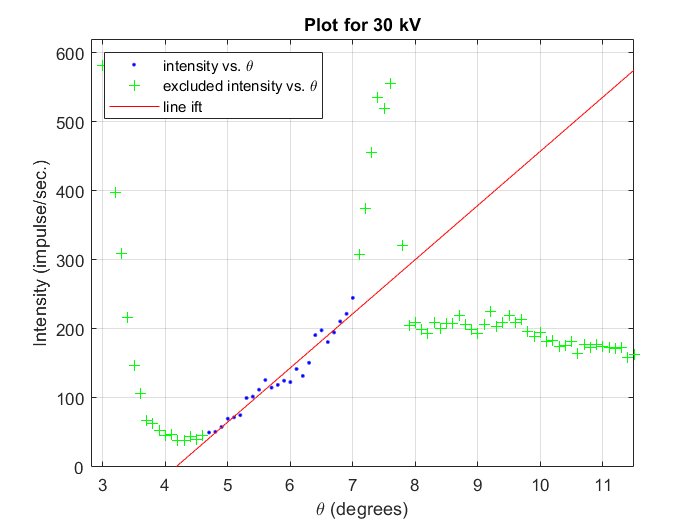

[xData, yData] = prepareCurveData( theta30kV, Rateat30kV );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164 165 166 167 168 169 170 171] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'Rateat30kV vs. theta30kV', 'Excluded Rateat30kV vs. theta30kV', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel theta30kV
ylabel Rateat30kV
grid on

xlim([2.81 11.50])
ylim([0 620])
legend({'intensity vs. \theta','excluded intensity vs. \theta','line ift'},'Location','northwest')
title('Plot for 30 kV')
xlabel('\theta (degrees)')
ylabel('Intensity (impulse/sec.)')


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =       78.41  (70.72, 86.1)    \pm 3.84
 %      p2 =      -326.8  (-372.1, -281.5) \pm 22.6

%Goodness of fit:
 % SSE: 3479
  %R-square: 0.9531
  %Adjusted R-square: 0.951
  %RMSE: 12.57
  
 %\theta_min= 4.168 \pm 0.353